PONG SINGLE PLAYER

*Stato (Observation):*

L’osservazione dello stato del gioco è rappresentata da quattro variabili:

- yBar: La coordinata verticale (altezza) della barra.

- xBall: La coordinata orizzontale (lunghezza) della pallina.

- yBall: La coordinata verticale (altezza) della pallina.

- theta: L’angolo di movimento della pallina (compreso tra 0° e 360°).

*Azione (Action):*

L’agente può intraprendere una delle seguenti azioni:

- 0: La barra rimane ferma.

- 0.7: La barra si muove verso l’alto di 0.7 unità.

- -0.7: La barra si muove verso il basso di 0.7 unità.

*Regole del gioco:*

La grandezza del campo di gioco è 30 * 30 unità.

La barra si trova nel lato sinistro del campo di gioco, con il suo punto centrale iniziale alle coordinate (2, 15).

La barra ha un’altezza di 5 unità e uno spessore di 1 unità.

La pallina inizia nel punto (15, 15) e può muoversi in un angolo compreso tra 0° e 15° e tra 315° e 360°.

Ad ogni step, la pallina si sposta di 1 unità con l’angolo theta.

Create customized Enviroment Interafce

obsInfo = rlNumericSpec([4 1]);
obsInfo.Name = "Pong States";
obsInfo.Description = 'yBar, xBall, yBall, theta';
actInfo = rlFiniteSetSpec([-0.7 0 0.7]);
actInfo.Name = "Pong Action";

type resetFunction.m

function [InitialObservation, Info] = resetFunction()

    yBar = 15;
    xBall = 15;
    yBall = 15;
    
    angolo_min1 = deg2rad(0);
    angolo_max1 = deg2rad(45);
    angolo_min2 = deg2rad(315);
    angolo_max2 = deg2rad(360);
    
    r = rand;
    
    if r < 0.5
        theta = angolo_min1 + (angolo_max1-angolo_min1).*rand;
    else
        theta = angolo_min2 + (angolo_max2-angolo_min2).*rand;
    end
    
    Info = [yBar;xBall;yBall;theta];
    InitialObservation = Info;

end


resetFnc = @resetFunction

resetFnc = function_handle with value:
    @resetFunction


type stepFunction.m

function [NextObs,Reward,IsDone,NextState] = stepFunction(Action,State)

    velBall = 1;
    xBar = 1;
    lBar = 1;
    hBar = 5;
    lBall = 1;
    lField = 30;
    hField = 30;
    Penalty = -20;

    %plotEnvironment(State);

    yBar = State(1)+Action;
    xBall = State(2);
    yBall = State(3);
    theta = State(4);
    
    % Calcolo della nuova posizione della pallina
    xBall = xBall + velBall * cos(theta);
    yBall = yBall + velBall * sin(theta);

    % Controllo se la barra esce dal campo
    if yBar >= hField - hBar/2
        yBar = hField - hBar/2;
    end
    if yBar <= hBar/2
        yBar = hBar/2;
    end
    
    % Controllo se la pallina ha colpito la barra
    if xBall <= xBar + lBar && yBall <= yBar + hBar/2 && yBall >= yBar - hBar/2
        % Calcolo del nuovo angolo dopo la collisione con la barra
        theta = pi - theta;
    end
    
    % Controllo se la pallina ha colpito il bordo superiore o inferiore del campo
    if yBall <= 0 || yBall >= hField
      

stepFnc = @stepFunction

stepFnc = function_handle with value:
    @stepFunction


env = rlFunctionEnv(obsInfo, actInfo, stepFnc, resetFnc);

Create DQN Agent

net = [
    featureInputLayer(obsInfo.Dimension(1))
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(length(actInfo.Elements))
    ];
criticNet = dlnetwork(net);
%deepNetworkDesigner(net)

critic = rlVectorQValueFunction(net, obsInfo, actInfo);

agentOpts = rlDQNAgentOptions();
agentOpts.UseDoubleDQN = false;
agentOpts.EpsilonGreedyExploration.Epsilon = 1;
agentOpts.EpsilonGreedyExploration.EpsilonMin = 0.001;
agentOpts.EpsilonGreedyExploration.EpsilonDecay = 0.001;
agentOpts.CriticOptimizerOptions.LearnRate = 1e-03;
agentOpts.DiscountFactor = 0.99;

agent = rlDQNAgent(critic, agentOpts);

Train Agent

trainOpts = rlTrainingOptions(...
    MaxEpisodes=3000, ...
    MaxStepsPerEpisode=700, ...
    Verbose=false, ...
    Plots="training-progress",...
    StopTrainingValue=700, ...
    ScoreAveragingWindowLength = 50, ...
    StopTrainingCriteria="AverageReward");
%plot(env);
info = train(agent, env, trainOpts)

info =   rlTrainingResult with properties:

           EpisodeIndex: [3000×1 double]
          EpisodeReward: [3000×1 double]
           EpisodeSteps: [3000×1 double]
          AverageReward: [3000×1 double]
        TotalAgentSteps: [3000×1 double]
           AverageSteps: [3000×1 double]
              EpisodeQ0: [3000×1 double]
         SimulationInfo: [3000×1 struct]
    EvaluationStatistic: [3000×1 double]
        TrainingOptions: [1×1 rl.option.rlTrainingOptions]


plot(info.EpisodeReward)

save("trainedAgent3.mat", "agent")

Simulate DQN Agent

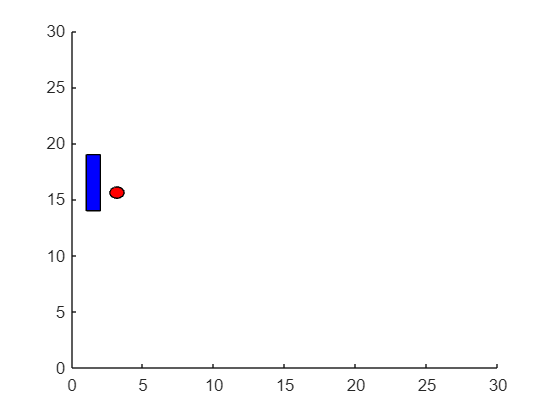

load("trainedAgent3.mat", "agent")
state = env.ResetFcn();
step = 500;
isDone = false;
while ~isDone && step>0
   action = agent.getAction(state);
   [nextObs, reward, isDone, nextState] = env.StepFcn(action{1}, state);
   state = nextState;
   step = step -1;
end